% Experiment Number 2 - Solution of Transcendental Equation by False Position Method- Accuracy Based Code
% Name of Programmer - Sahil Patra
% Roll No - 124MM0055

clc
clear all
f = @(x) x.*log10(x)-1.2

f = function_handle with value:
    @(x)x.*log10(x)-1.2


acc = input("\n Enter the Accuracy ");
a= input("\nEnter First Guess ");
b= input("\nEnter Second Guess ");
while f(a)*f(b)>0
    fprintf(" The Guesses are incorrent");
    a = input("\nEnter a new First Guess ");
    b = input("\nEnter a new Second Guess ");  
end
c = a-(f(a)*((a-b)/(f(a)-f(b))));
ni= 0;
while abs(f(c))>acc
     c = a-(f(a)*((a-b)/(f(a)-f(b)))); 
     ni = ni+1;
    if f(a) * f(c) < 0 
        b = c;
    else 
        a = c;
    end
end

fprintf('The root is approximately: %.6f\n', c);

The root is approximately: 2.740646



fprintf("The Count Required is = %.6f",ni);

The Count Required is = 4.000000

x1=linspace(-10,10,100);
y= f(x1);
plot(x1, y,"r",LineWidth=2);

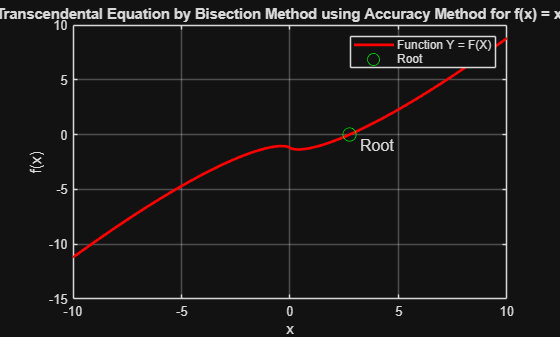

xlabel('x');
ylabel('f(x)');
title('Solution of Transcendental Equation by False Position Method using Accuracy Method for f(x) = x * log10(x) - 1.2');
grid on
hold on
plot(c, f(c), 'go', 'MarkerSize', 10);
text (c+0.5,f(c)-1,"Root",FontSize=12)
legend ("Function Y = F(X)","Root")